%Solution 2
syms s a b0 b1 b2

%Acd(s)
expand( (s^2+4*s+9)*(s+10)^2*(s+1)*(s+4)  )

$$ans = s^{6}+29\,s^{5}+313\,s^{4}+1621\,s^{3}+4556\,s^{2}+6820\,s+3600$$


%Ac(s)
expand( (-s+4)*(b2*s^2+b1*s+b0)*(s+1)*(s+4) + (s^2+0.25^2)*(s+1)*(s+4)*s*(s+a) )

$$ans = 16\,b_{0}+\frac{a\,s}{4}+16\,b_{0}\,s+16\,b_{1}\,s+\frac{5\,a\,s^{2}}{16}+\frac{65\,a\,s^{3}}{16}+5\,a\,s^{4}+a\,s^{5}-b_{0}\,s^{2}-b_{0}\,s^{3}+16\,b_{1}\,s^{2}-b_{1}\,s^{3}+16\,b_{2}\,s^{2}-b_{1}\,s^{4}+16\,b_{2}\,s^{3}-b_{2}\,s^{4}-b_{2}\,s^{5}+\frac{s^{2}}{4}+\frac{5\,s^{3}}{16}+\frac{65\,s^{4}}{16}+5\,s^{5}+s^{6}$$


%finding controller response
a = 31116/257;
b0 = 225;
b1 = 819761/4112;
b2 = 24948/257;
C = (b2*s^2+b1*s+b0)/((s^2+0.25^2)*s*(s+a));
G = (-s+4)/((s+1)*(s+4))

$$G = -\frac{s-4}{\left(s+1\right)\,\left(s+4\right)}$$

P = C*G;
R = 0.25/(s^2+0.25^2);
Y = (P/(1+P))*R;

c = ilaplace(C);
y = ilaplace(Y);

t = 8

t = 8

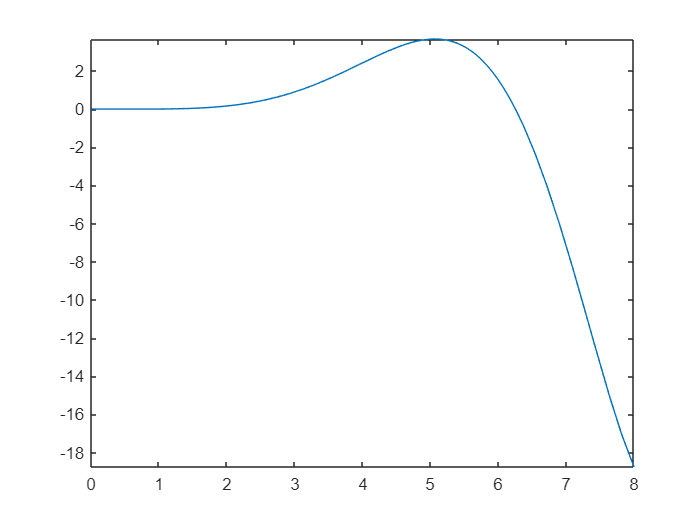

fplot(y,[0 t])

%fplot(u,[0 t])
%}

%Lecture example solution, pg 10
syms s
C = (10*s^2 + 23*s + 31)/(s^2+4)
P = 1/(s-1)
U = (C)*(2/(s^2+4))
S = 1/(1+C*P)
Y = S*d
u = ilaplace(U)

t = 100
fplot(u,[0 t])